# 覆盖模型

% 主要用作节点的覆盖研究

### **初始化变量**

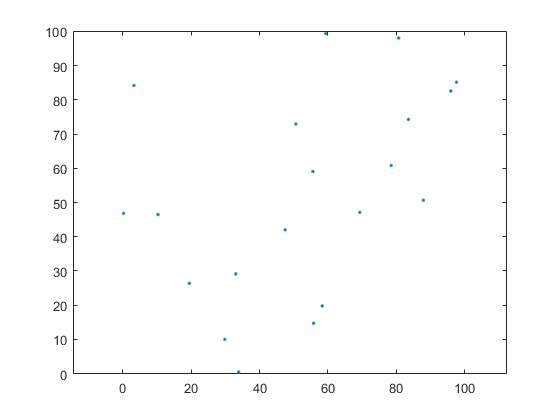

% 检测区域半径
wsn.r_all=50;
% 检测区域形状
wsn.shape='square';
% 传感器数量·  
wsn.num=20;

% ----覆盖参数----
% 网格均分数（此数越小计算越快，越不准确）
wsn.co_x=50;

wsn.co_set='index';
% bool（布尔）覆盖模型参数
wsn.co_r=20;
% index（指数）覆盖模型参数
wsn.co_r1=10;
wsn.co_r2=20;
wsn.co_L=0.1;
% ---------------

wsn.point=wsn_point_create(wsn);
% 节点分布图
figure();plot(wsn.point(:,1),wsn.point(:,2),'.');
axis([0 2*wsn.r_all 0 2*wsn.r_all]);axis equal

### 对节点初始部署

% 粒子群部署（注释掉就是随机部署）
wsn=deploy_pso(wsn);


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              20          -0.873         -0.7777        0
  200            4020         -0.9732         -0.9569        0
  400            8020         -0.9746         -0.9745        2
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


### 统计变量

% 当前覆盖率
cov=mean(mean(cover(wsn)))

cov = 0.9746

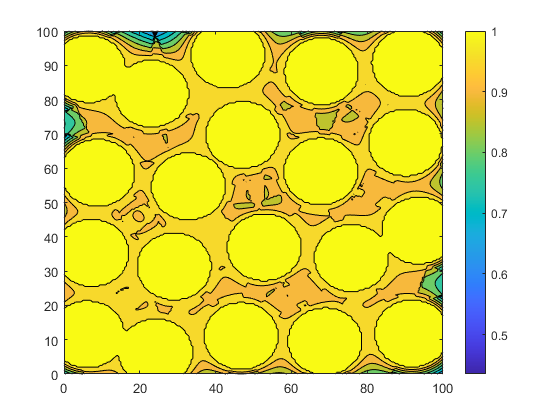

% 覆盖热点图
wsn.co_x=200;
wsn_plot_cov(wsn)